# Gröbner Basis

### Polynomial Division

- Leading monomial: Monomial of the polynomial with the highest degree.

- Leading coefficient: Coefficient of the leading monomial.

- Degree of polynomial: Degree of the leading term.

- *Degree of remainder always lesser than that of the divisor.*

### Monomial Orderings

- Lexicographic ordering or Lex ordering: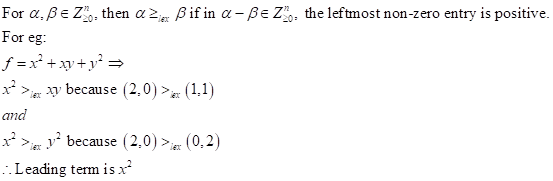

- Graded lexicographic ordering:

               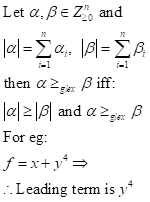

### Multi-variate Polynomial Division

- Dividing 2 polynomials:

              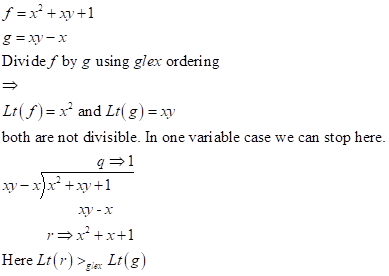

clear all;clc
syms x y
f = x^2+x*y+1;
d = x*y-x;
[r,q] = polynomialReduce(f,d)

$$r = x^{2}+x+1$$

$$q = 1$$

- Dividing by a system of polynomials: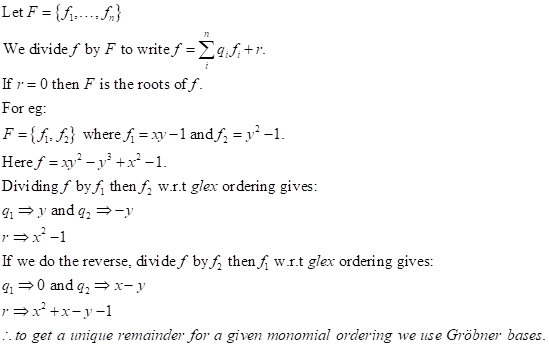

syms x y
f = x*y^2-y^3+x^2-1;
d1 = [x*y - 1, y^2 - 1];
d2 = [y^2 - 1, x*y - 1];
[r1,q1] = polynomialReduce(f,d1)

$$r1 = x^{2}-1$$

$$q1 = \left(\begin{array}{cc} y & -y \end{array}\right)$$

[r2,q2] = polynomialReduce(f,d2)

$$r2 = x^{2}+x-y-1$$

$$q2 = \left(\begin{array}{cc} x-y & 0 \end{array}\right)$$

### Rings

A ring is a non-empty set equipped with 2 operations that satisfy the following axioms:

- It is closed under addition: $if \ a \in R \ and \ b \in R \ then \ a+b \in R$

- Associative

- Commutative

- Should have additive identity: $i.e \ 0_R \in a \ such\ that\ a+0_R=a=0_R+a \  \forall a \in R$

- Should have additive inverse.

- Closed under multiplication:$if\ a \in R\ and\ b\in R\ then\ a\bullet b \in R$

- Distributive and assosiative.

- *A set of ****Z****, ****Q**** and ****C**** are rings. Set of even numbers form a ring but set of odd nos don’t.*

### Ideals & Fields

- A subring *I* of a ring *R* is an **ideal** *iff *when* r **∈** R *and*a **∈ I, *then* r.a **∈** I *and *a.r **∈ I*. For eg. a set of even integers is an ideal of the ring ***Z*** and $\{0_R\}$ and ***R*** are ideals for every ring ***R***.

             

- The zero ideal is generated by a single element set; *I=<*$0_R$*>={*$0_R$*} **∀ *ring ***R***.

- Ideals can have different set of generators.

- Noetherian Rings: A ring ***R*** is a Noetherian ring if every ideal *I* of ***R*** is finitely generated. And, according to Hilbert’s Basis Theorem if *R* is a Noetherian ring then so is the polynomial ring *R[x]*.

### Gröbner Basis

(LM(*f*) denotes fixed monomial ordering and LT(*f*) denotes the leading term.)

- A **Gröbner basis** is a set of multivariate nonlinear polynomials enjoying certain properties that allow simple algorithmic solutions for many fundamental problems in mathematics and natural and technical sciences.

- An arbitrary set of polynomials is in general not a Gröbner basis. However, for every basis $F$ there exists a Gröbner basis $G$ which is equivalent to $F$ in the sense that the linear combinations of elements of $F$ are precisely the same as the linear combinations of elements of $G$. For $F$ and $G$ equivalent in this sense, the congruence of polynomials modulo $F$ agrees with the congruence modulo $G$.

- Given an arbitrary basis $F$, an equivalent Gröbner basis $G$ can be found constructively by Buchberger's Algorithm.

- A Gröbner basis of an ideal *I* is a set of generators of *I*.

- For a fixed monomial ordering a finite subset *G=*$\{g_1,...,g_t\}$ of an ideal *I* is said to be a Gröbner basis if:$<LT(g_1),...,LT(g_t)>=<LT(I)>$

- For a linear system of equations Grobner Basis is basically the Row Echelon form. For a univariate system of equations it is the GCD($f_1,...,f_m$). In general for an ideal **I **the Grobner basis consists of all the "smallest polynomials" in **I** for a given monomial ordering.

- S-polynomials: 

             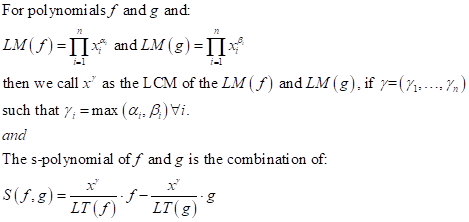

- For example:

             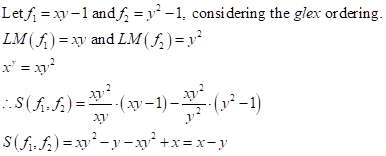

### Buchberger's Algorithm

    A variety of frequently arising questions about sets of polynomial equations can be answered easily when the sets are "Gröbner bases" while they are not easy to answer for an arbitrary set of polynomials. Buchberger's algorithm provides a means to transform an arbitrary set of polynomials into an equivalent Gröbner basis. Therefore, questions about some set of polynomials arising in an application can be answered by first using Buchberger's algorithm to compute an equivalent Gröbner basis and then answering the question for the Gröbner basis.

Gröbner basis is a reduction step of a polynomial *p* with respect to a fixed set *B* of polynomials consists of subtracting some multiple of an element of *B* from *p* in such a way that some power product in *p* is replaced by power products which are smaller (w.r.t. a fixed order imposed on the power products).

Repeated reduction steps, after finitely many steps, will always lead to some polynomial which cannot be reduced any further. Such a polynomial is called a *reduced form* of *p* with respect to *B* . Reduced forms are in general not unique. However, one can give an algorithm which for given *p* and *B* computes *some* reduced form of *p* with respect to *B* . By RED we denote such a function, i.e., RED(*p*,*B*) is a reduced form of *p* with respect to *B* obtained by repeated reduction steps.

We also recall from the Gröbner basis article that the S-polynomial of two polynomials *p* and *q* is defined as:


$$S(f,g)=LCM(LT(f),LT(g))(\frac{f}{LM(f)}-\frac{g}{LM(g)})$$


where the symbols LT and LM refer to the leading power product and the leading monomial (w.r.t. a fixed order imposed on the power products), and LCM to the least common multiple.

**Termination** of the algorithm is shown by considering the leading power products of the polynomials in *G* . A leading power product of some new polynomial *h* cannot be a multiple of a leading power product of a polynomial in *G* , because the polynomials *h* are completely reduced with respect to *G* . If on some input the algorithm did not terminate, this would give rise to an infinite sequence of power products in which none is a multiple of any power product appearing earlier in the sequence.

Rough algorithm:

- Chose the monomial ordering.

- Start with *G := F*.

- Repeat G’ := G until G = G’

              For example:

             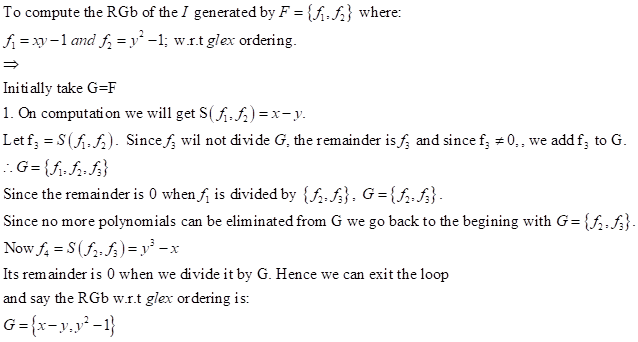

syms x y
r = [x*y-1, y^2-1];

$$G = \left(\begin{array}{cc} y^{2}-1 & x-y \end{array}\right)$$

G = gbasis(r)

Proper algorithm:

Input: A finite set *F* of polynomials.

Output: A finite Gröbner basis *G *equivalent to *F*

- 
$$G:=F$$


- 
$$C:=G\times G$$


- while $C \neq \emptyset$ do

-     choose a pair $(f,g)$ from $C$

-     
$$C:=C/ \{(f,g)\}$$


-     
$$h:=RED(S(f,g),G)$$


-     if $h \neq 0$ then

-         
$$C:=C \cup (G \times \{h\})$$


-         
$$G:=G\cup \{h\}$$


- return $G$

### Unique Remainders

- For example:

            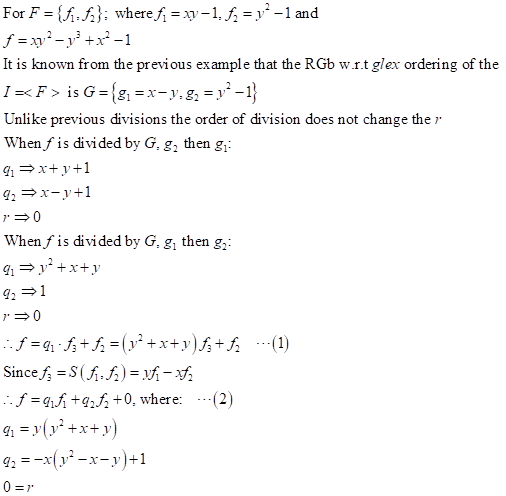

syms x y
f = x*y^2-y^3+x^2-1;
d = [x*y-1,y^2-1];
G = gbasis(d);
Gd = [G(1,2) G(1,1)];

$$r1 = 0$$

$$q1 = \left(\begin{array}{cc} x-y+1 & x+y+1 \end{array}\right)$$

[r1,q1] = polynomialReduce(f,G)

$$r2 = 0$$

$$q2 = \left(\begin{array}{cc} y^{2}+y+x & 1 \end{array}\right)$$

[r2,q2] = polynomialReduce(f,Gd)

        A zero remainder implies that the solutions of *F* are the roots of *f*. In conclusion, to divide a polynomial *f* by a set of polynomials *F* to get a unique remainder the following steps are to be followed:

- Compute Gröbner basis $G=\{g_1,...,g_t\}$ of the ideal *I=<F>.*

- Divide *f* by *G *to get a unique remainder *r*.

- Trace the quotients$q_i,\ i=1\ to\ n$ from the S-polynomials to write $f=q_1f_1+...+q_nf_n+r$

### Applications in Inverse Kinematics

#### Consider a robot with 2 revolute joints.

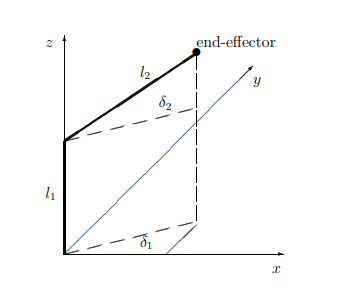

here we have 9 parameters; $l_1,l_2,p_x,p_y,p_z,\delta_1,\delta_2,s_1,s_2,c_1,c_2$ where $l_1,l_2$ are the link lengths; $p_x,p_y,p_z$ are the end-effector x-, y- and z- coordinates; $\delta_1, \delta_2$ are the angles describing the revolutions of the revolute joints; and $s_1,s_2,c_1,c_2$ are the sines and cosines of $\delta_1 \ and \ \delta_2$. 

        So with these we consider a system of equations:

given $l_1,l_2,p_x,p_z,$

solve for $s_1,s_2,c_1,c_2,p_y$

syms l1 l2 px pz s1 s2 c1 c2 py

Using these we can get 5 equations:


$$l_2.c_1.c_2-p_x=0,\\
l_2.s_1.c_2-p_y=0,\\
l_2.s_2 + l_1-p_z=0,\\
c_{1}^{2}+s_{1}^{2}-1=0\\
c_{2}^{2}+s_{2}^{2}-1=0$$


F = [l2*c1*c2 - px, l2*s1*c2-py, l2*s2+l1-pz, c1^2+s1^2-1, c2^2+s2^2-1];
G = gbasis(F,[c1 c2 s1 s2 py],'MonomialOrder','lexicographic');
siz = size(G);
for i=1:siz(2)
    disp(G(i))
end

$$c_{1}+\frac{\mathrm{px}\,\mathrm{py}\,s_{1}}{{l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}}$$

$$c_{2}+\frac{\mathrm{py}\,s_{1}\,\left(-{l_{1}}^{2}+2\,l_{1}\,\mathrm{pz}+{l_{2}}^{2}-{\mathrm{pz}}^{2}\right)}{l_{2}\,\left({l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}\right)}$$

$$\frac{{l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{pz}}^{2}}{-{l_{1}}^{2}+2\,l_{1}\,\mathrm{pz}+{l_{2}}^{2}-{\mathrm{pz}}^{2}}+{s_{1}}^{2}$$

$$s_{2}+\frac{l_{1}-\mathrm{pz}}{l_{2}}$$

$${l_{1}}^{2}-2\,l_{1}\,\mathrm{pz}-{l_{2}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}$$

These can be transformed into a Grobner Basis in the polynomial ring $\mathbb{Q}(l_1,l_2,p_x,p_z)[c_1,c_2,s_1,s_2,p_y]$:

This gives us 5 equations and 5 unknowns and thus solves the problem. Let:


$$l_1=30\\ l_2=45\\
p_x=\frac{45}{4}\sqrt{6}\\
p_z=\frac{45}{2}\sqrt{2}+30$$


L1 = 30;L2 = 45; PX = 45*sqrt(6)/4; PZ = 45*sqrt(2)/2+30;

subs1 = subs(G(5), [l1, l2, px, pz], [L1, L2, PX, PZ]);
sol1 = solve(subs1 , py,'ReturnConditions',true);

py=


disp('py=')

$$\left(\begin{array}{c} -15.9099\\ 15.9099 \end{array}\right)$$

disp(vpa(sol1.py,6))
siz = size(sol1.py);
if(siz(1) > 1)
    PY = vpa(sol1.py(2),6);
else
    PY = vpa(sol1.py,6);
end

Here we get py=$\left(\begin{array}{c}
-15.9099\\
15.9099
\end{array}\right)$. We take py=15.9099

subs2 = subs(G(4), [l1, l2, pz], [L1, L2, PZ]);
sol2 = solve(subs2 , s2,'ReturnConditions',true);

s2=


disp('s2=')

$$0.707107$$

disp(vpa(sol2.s2,6))
siz = size(sol2.s2);
if(siz(1) > 1)
    S2_1 = vpa(sol2.s2(2),6);
else
    S2_1 = vpa(sol2.s2,6);
end

s2=$0.707107$

subs3 = subs(G(3), [l1, l2, px, pz], [L1, L2, PX, PZ]);
sol3 = solve(subs3 , s1,'ReturnConditions',true);

s1=


disp('s1=')

$$\left(\begin{array}{c} -0.5\\ 0.5 \end{array}\right)$$

disp(vpa(sol3.s1,6))
siz = size(sol3.s1);
if(siz(1) > 1)
    S1_1 = vpa(sol3.s1(2),6);
else
    S1_1 = vpa(sol3.s1,6);
end

s1=$\left(\begin{array}{c}
-0.5\\
0.5
\end{array}\right)$. We take s1=0.5

subs4 = subs(G(2), [s1, l1, l2, px, py, pz], [S1_1, L1, L2, PX, PY, PZ]);
sol4 = solve(subs4 , c2,'ReturnConditions',true);

c2=


disp('c2=')

$$0.707107$$

disp(vpa(sol4.c2,6))
siz = size(sol4.c2);
if(siz(1) > 1)
    C2_1 = vpa(sol4.c2(2),6);
else
    C2_1 = vpa(sol4.c2,6);
end

c2=$0.707107$

subs5 = subs(G(1), [s1, l1, l2, px, py, pz], [S1_1, L1, L2, PX, PY, PZ]);
sol5 = solve(subs5 , c1,'ReturnConditions',true);

c1=


disp('c1=')

$$0.866025$$

disp(vpa(sol5.c1,6))
siz = size(sol5.c1);
if(siz(1) > 1)
    C1_1 = vpa(sol5.c1(2),6);
else
    C1_1 = vpa(sol5.c1,6);
end

and c1=$0.866025$

Thus the problem is solved with:


$$l_1=30;l_2=45,\\
p_x=\frac{45}{4}\sqrt{6}\\
p_z=\frac{45}{2}\sqrt{2}+30\\
and\ the\ solved\ variables\ are:\\
p_y=15.9099\\
s_2=0.707107\\
s_1=0.5\\
c_2=0.707107\\
c_1=0.866025$$


and the angles are:

del1 = vpa(rad2deg(acos(C1_1)),6);
del2 = vpa(rad2deg(acos(C2_1)),6);

𝛿1=


disp('𝛿1=')

$$30.0$$

disp(del1);

𝛿2=


disp('𝛿2=')

$$45.0$$

disp(del2);


#### Now considering a 3-DOF 5R Robot.

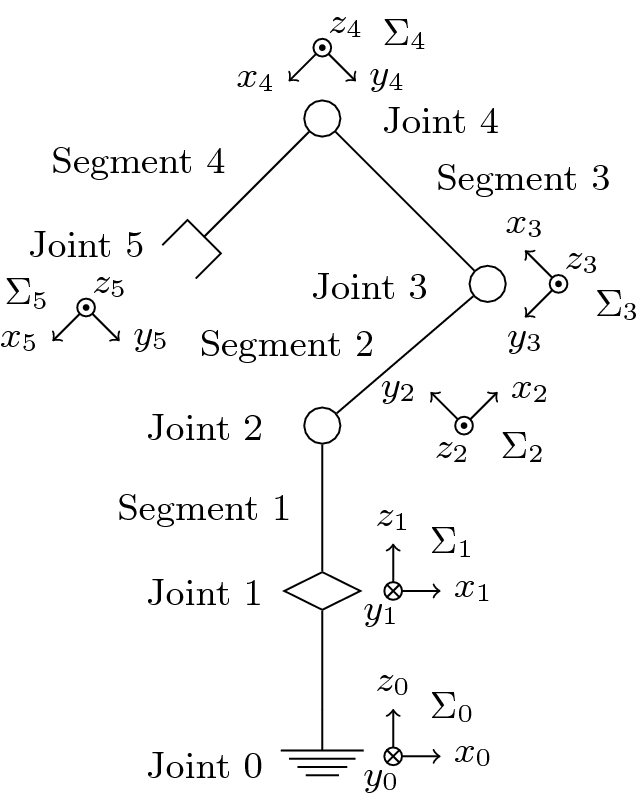

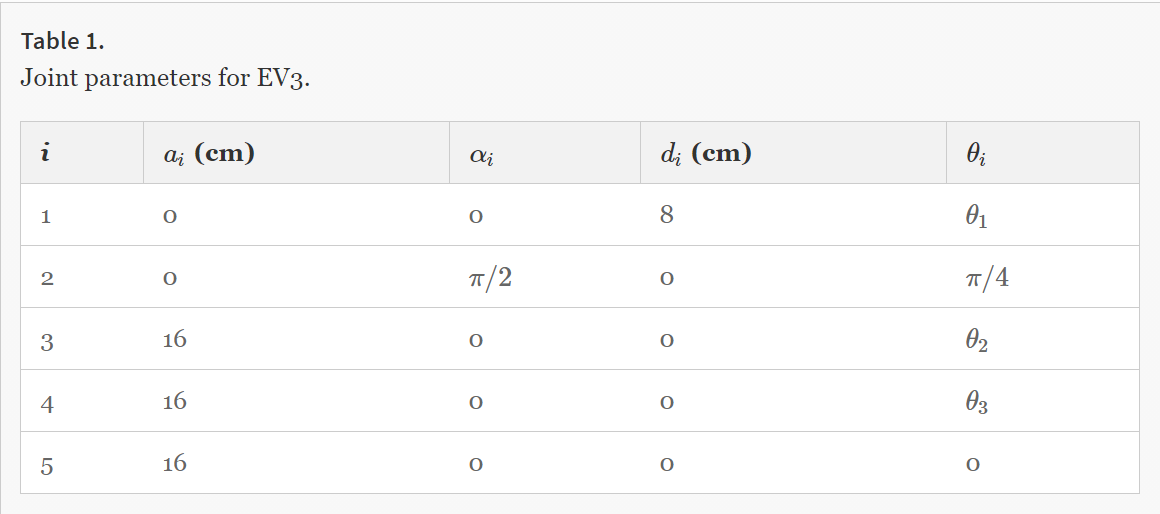

- where EV3 is the manipulator being used in this example.

DH convention to express transformation from $(i-1)^{th}
$ system to $i^{th}$ system.


$$T^{i-1}_i = 
\pmatrix{
    1 & 0 & 0 & a_i 
\cr 0 & 1 & 0 & 0
\cr 0 & 0 & 1 & 0 
\cr 0 & 0 & 0 & 1}

\pmatrix{
    1 & 0 & 0 & 0
\cr 0 & cos(\alpha_i) & -sin(\alpha_i) & 0
\cr 0 & sin(\alpha_i) & cos(\alpha_i) & 0
\cr 0 & 0 & 0 & 1}

\pmatrix{
    1 & 0 & 0 & 0
\cr 0 & 1 & 0 & 0
\cr 0 & 0 & 1 & d_i
\cr 0 & 0 & 0 & 1}

\pmatrix{
 cos(\theta_i) & -sin(\theta_i) & 0 & 0
\cr sin(\theta_i) & cos(\theta_i) & 0 & 0
\cr    0 & 0 & 1 & 0
\cr 0 & 0 & 0 & 1}

\\
\ \ \ \  = \pmatrix{
 cos(\theta_i) & -sin(\theta_i) & 0 & a_i
\cr cos(\alpha_i)sin(\theta_i) & cos(\alpha_i)cos(\theta_i) & -sin(\alpha_i) & -d_i\ sin(\alpha_i)
\cr sin(\alpha_i)sin(\theta_i) & sin(\alpha_i)cos(\theta_i) & cos(\alpha_i) & d_i\ cos(\alpha_i)
\cr 0 & 0 & 0 & 1}$$


where $a_i$ is the distance beween $z_{
i-1}$ and $z_{i
}$, $\alpha_{
i}$ is the angle between axes $z_{
i-1}$ and $z_{i
}$ with respect to $x_{i
}$ axis, $d_{i
}$ is the distance between $x_{i-1
}$ and $x_{i
}$, and $\theta_{i
}$ the angle between axes $x_{i-1
}$ and $x_{i
}$ with respect to $z_{i
}$ axis.

Thus we can get $T_5^0 = T_1^0 T_2^1 T_3^2 T_4^3 T_5^4$ and the end effector position is the translation part of the matrix.


$$\pmatrix{x \cr y \cr z} = 

\pmatrix{t_{14} \cr t_{24} \cr t_{34}}$$


syms th1 th2 th3
the = [th1, pi/4, th2, th3, 0];
d = [8, 0, 0, 0, 0];
alp = [0, pi/2, 0, 0, 0];
a = [0, 0, 16, 16, 16];
T0_1 = getMat(a(1), alp(1),d(1),the(1));
T1_2 = getMat(a(2), alp(2),d(2),the(2));
T2_3 = getMat(a(3), alp(3),d(3),the(3));
T3_4 = getMat(a(4), alp(4),d(4),the(4));
T4_5 = getMat(a(5), alp(5),d(5),the(5));
T0_5 = T0_1*T1_2*T2_3*T3_4*T4_5;
% simplify(vpa(T0_5,2))
x = 12;
y = 9;
z = 4;

EP =     12
     9
     4


EP = [x ; y ; z]

syms c1 s1 c2 s2 c3 s3
f1 = 8*sqrt(2)*c1*(c2+c3*(c2-s2)-s2-s3*(c2+s2)+1) - x;
f2 = 8*sqrt(2)*s1*(c2+c3*(c2-s2)-s2-s3*(c2+s2)+1) - y;
f3 = 8*sqrt(2)*(c2+c3*(c2+s2)+s2+s3*(c2-s2)+1) + 8 - z;
f4 = s1^2 + c1^2 - 1;
f5 = s2^2 + c2^2 - 1;
f6 = s3^2 + c3^2 - 1;

F = [f1,f2,f3,f4,f5,f6];
G = gbasis(F,[c1 c2 s1 s2 c3 s3],'MonomialOrder','lexicographic');

[a1,a2,a3,a4,a5,a6] = solve(G,[c1 s1 c2 s2 c3 s3]);
C1_1 = double(vpa(a1(1),3));
S1_1 = double(vpa(a2(1),3));
C2_1 = double(vpa(a3(1),3));
S2_1 = double(vpa(a4(1),3));
C3_1 = double(vpa(a5(1),3));
S3_1 = double(vpa(a6(1),3));

C1_2 = double(vpa(a1(2),3));
S1_2 = double(vpa(a2(2),3));
C2_2 = double(vpa(a3(2),3));
S2_2 = double(vpa(a4(2),3));
C3_2 = double(vpa(a5(2),3));
S3_2 = double(vpa(a6(2),3));

theta1_1 = rad2deg(acos(C1_1));
theta2_1 = rad2deg(acos(C2_1));
theta3_1 = rad2deg(acos(C3_1));

theta1_2 = rad2deg(acos(C1_2));
theta2_2 = rad2deg(acos(C2_2));
theta3_2 = rad2deg(acos(C3_2));


Orientation 1:


disp("Orientation 1:")

θ1=143.1301


disp("θ1="+theta1_1)

θ2=147.2651


disp("θ2="+theta2_1)

θ3=35.8657


disp("θ3="+theta3_1)


Orientation 2:


disp("Orientation 2:")

θ1=143.1301


disp("θ1="+theta1_2)

θ2=176.8692


disp("θ2="+theta2_2)

θ3=35.8657


disp("θ3="+theta3_2)

function T = getMat(a, alp, d, the)
T = [cos(the), -sin(the), 0, a;
     cos(alp)*sin(the), cos(alp)*cos(the), -sin(alp), -d*sin(alp);
     sin(alp)*sin(the), sin(alp)*cos(the), cos(alp), d*cos(alp);
     0, 0, 0, 1];
end